%% GCN su dataset di volti (Eigenfaces)
% Questo script costruisce un grafo di similarità tra le immagini (Eigenfaces),
% addestra una GCN artigianale (1 layer) e valuta la classificazione.

%% 1) Caricamento e preparazione dati
load('dataset/volti_dataset_Yale.mat');   % A, labels
load('results/mean_face.mat');
load('results/svd_data.mat');        % U

k = 100;
U_k = U(:, 1:k);
A_centered = A - mean_face;
X = (U_k' * A_centered)';   % [n_samples x k]
num_samples = size(X,1);
num_classes = max(labels);

% One-hot encoding
Y = zeros(num_classes, num_samples);
for i = 1:num_samples
    Y(labels(i), i) = 1;
end

%% 2) COSTRUISCI IL GRAFO: matrice di adiacenza A_hat
K = 10;  % Numero vicini
A = zeros(num_samples, num_samples);
for i = 1:num_samples
    dists = sum((X - X(i,:)).^2, 2);
    [~, idx] = sort(dists);
    neighbors = idx(2:K+1);   % Esclude sé stesso
    A(i, neighbors) = 1;
end
A = max(A, A');  % Simmetrica
A_hat = A + eye(num_samples);

% Normalizza (A_hat): D^(-1/2) * A_hat * D^(-1/2)
D = diag(sum(A_hat, 2));
A_hat_norm = D^(-0.5) * A_hat * D^(-0.5);

%% 3) Split train/test
rng(0);
perm = randperm(num_samples);
split = round(0.8 * num_samples);
train_idx = perm(1:split);
test_idx  = perm(split+1:end);

X_train = X(train_idx, :);
Y_train = Y(:, train_idx);

X_test = X(test_idx, :);
Y_test = Y(:, test_idx);

A_train = A_hat_norm(train_idx, train_idx);

%% 4) Addestramento GCN
epochs = 100;
learning_rate = 0.01;

fprintf('--- Training GCN ---\n');

--- Training GCN ---


[W, loss_hist] = gcn_train(X_train, Y_train, A_train, epochs, learning_rate);

[GCN] Epoch  10/100 - Loss: 6.3183
[GCN] Epoch  20/100 - Loss: 4.3116
[GCN] Epoch  30/100 - Loss: 2.2504
[GCN] Epoch  40/100 - Loss: 1.6006
[GCN] Epoch  50/100 - Loss: 0.8320
[GCN] Epoch  60/100 - Loss: 1.7200
[GCN] Epoch  70/100 - Loss: 2.1903
[GCN] Epoch  80/100 - Loss: 1.6329
[GCN] Epoch  90/100 - Loss: 1.0109
[GCN] Epoch 100/100 - Loss: 0.9267



%% 5) Valutazione su test set
A_test = A_hat_norm(test_idx, train_idx);
Z_test = (A_test * X_train) * W;  % propagazione GCN
Z_test = Z_test';
Z_test = Z_test - max(Z_test,[],1);
expZ = exp(Z_test);
A2 = expZ ./ sum(expZ,1);
[~, y_pred] = max(A2,[],1);
[~, y_true] = max(Y(:, test_idx), [], 1);
acc = mean(y_pred' == y_true');
fprintf('Test accuracy (GCN): %.2f%%\n', acc*100);

Test accuracy (GCN): 81.71%


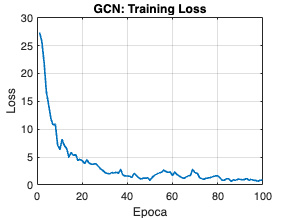


%% 6) Visualizzazione loss
figure;
plot(1:epochs, loss_hist, 'LineWidth', 1.5);
xlabel('Epoca'); ylabel('Loss');
title('GCN: Training Loss');
grid on;